# Problema 2 - Suplimentar

function coef = hermite_coef_cubic(x, f, df)
% HERMITE_COEF_CUBIC - Generează coeficienții spline-ului Hermite cubic
%
% INPUT:
%   x  - vectorul nodurilor [x0, x1, ..., xn]
%   f  - valorile functiei f(x) in noduri
%   df - valorile derivatei f'(x) in noduri
%
% OUTPUT:
%   coef - matrice (n-1)x4 cu coeficientii [a, b, c, d] pentru fiecare polinom

    n = length(x);
    coef = zeros(n-1, 4);  % Fiecare linie: coeficientii pentru un polinom Hermite

    for i = 1:n-1
        h = x(i+1) - x(i);
        f0 = f(i); f1 = f(i+1);
        d0 = df(i); d1 = df(i+1);

        % Forma canonica a Hermite-ului cubic
        a = f0;
        b = d0;
        c = (3*(f1 - f0)/h^2) - (2*d0 + d1)/h;
        d = (2*(f0 - f1)/h^3) + (d0 + d1)/h^2;

        coef(i, :) = [a, b, c, d];
    end
end

function y = eval_hermite_cubic(x, coef, xx)
% EVAL_HERMITE_CUBIC - Evalueaza spline-ul Hermite cubic
%
% INPUT:
%   x    - vectorul nodurilor [x0, ..., xn]
%   coef - coeficientii de la hermite_coef_cubic()
%   xx   - punctele de evaluare
%
% OUTPUT:
%   y - valori spline evaluate in xx

    y = zeros(size(xx));
    n = length(x);

    for j = 1:length(xx)
        idx = find(xx(j) >= x(1:end-1) & xx(j) <= x(2:end), 1);
        if isempty(idx)
            if xx(j) < x(1)
                idx = 1;
            else
                idx = n - 1;
            end
        end

        dx = xx(j) - x(idx);
        a = coef(idx,1); b = coef(idx,2);
        c = coef(idx,3); d = coef(idx,4);
        y(j) = a + b*dx + c*dx^2 + d*dx^3;
    end
end

function [yy, polinoame, eroare_max] = aplicaHermiteSpline(f, df, x, x_eval)
% APLICAHERMITESPLINE - Aplica interpolarea Hermite pentru functia f
%
% INPUT:
%   f      - functie f(x) (anonima)
%   df     - derivata f'(x) (anonima)
%   x      - noduri de interpolare
%   x_eval - puncte in care se evalueaza spline-ul
%
% OUTPUT:
%   yy         - valorile spline-ului evaluate in x_eval
%   polinoame  - celula cu expresiile simbolice ale polinoamelor Hermite
%   eroare_max - eroarea maxima absoluta

    y = f(x);
    dy = df(x);

    coef = hermite_coef_cubic(x, y, dy);
    yy = eval_hermite_cubic(x, coef, x_eval);

    % Formule simbolice
    syms xx
    polinoame = cell(1, length(x)-1);
    for i = 1:length(x)-1
        dx = xx - x(i);
        S = coef(i,1) + coef(i,2)*dx + coef(i,3)*dx^2 + coef(i,4)*dx^3;
        polinoame{i} = simplify(S);
    end

    % Eroare maxima
    eroare_max = max(abs(f(x_eval) - yy));
end

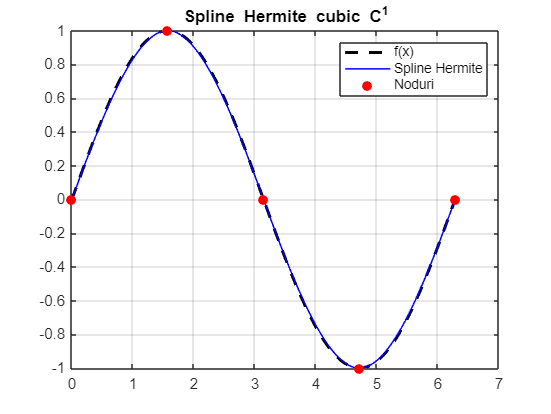

f = @(x) sin(x);          % Functia f(x)
df = @(x) cos(x);         % Derivata f'(x)

a = 0; 
b = 2*pi;
x_noduri = linspace(a, b, 5);      % noduri de interpolare
x_eval = linspace(a, b, 300);      % puncte de evaluare

[yy, p, err] = aplicaHermiteSpline(f, df, x_noduri, x_eval);

% Grafic
figure;
plot(x_eval, f(x_eval), 'k--', 'LineWidth', 2); hold on;
plot(x_eval, yy, 'b-', 'LineWidth', 1);
plot(x_noduri, f(x_noduri), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline Hermite', 'Noduri');
title('Spline Hermite cubic C^1');
grid on;


fprintf('Eroare maxima: %.2e\n', err);

Eroare maxima: 1.08e-02
